# Analyzing the Sun's Path

The position of the sun is an afterthought for most, unless it is blinding you on your commute home. However, the position of the sun remains incredibly important, even in the modern age. While solar navigation through sextants was common until GPS came along, architects/engineers still track the sun for building shading and solar panel optimization. This script dives into the "analemma" which is an interesting phenomenon associated with solar observations. Try testing different latitudes to see how the sun's trajectory changes and what the analemma looks like! 

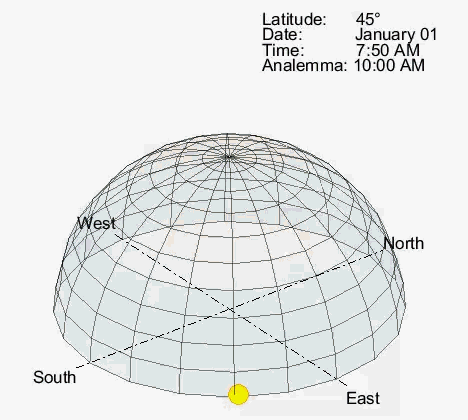

The trajectory of the sun in the sky depends on the time of year and the latitude of observation due to the tilt of Earth and the eccentricity of the orbit around the sun. The "analemma" is a phenomenon that results from the eccentricity and obliquity of Earth's orbit with the sun. If you set up a camera and take a photograph of the sun at 24 hour intervals over the course of a year, an "infinity-like" symbol will appear in the sky. The analemma represents the difference between "apparent solar time" (noon = sun directly overhead) versus "mean solar time" (clock counting 24 hour days).

observationLatitude = 45;               % Latitude (in deg) of solar observation
timeSnapshot = 10;                      % Snapshot time for analemma (hour)

% Vectors for time/date
time = hours(0):minutes(10):hours(24);  % Hours of day for solar observation
day = 1:365;                            % Days of the year

## Visualizing the Equation of Time

While the "Equation of Time" sounds like a band name for a noise-rock group that you started in college, the Equation of time actually describes the difference between apparent solar time and mean solar time. If the Earth's orbit was perfectly circular and had no tilt, the sun's peak would be exactly 24 hours apart each day. However, the elliptical nature of orbits and the tilt of Earth's orbital plane introduce slight variations into each day.

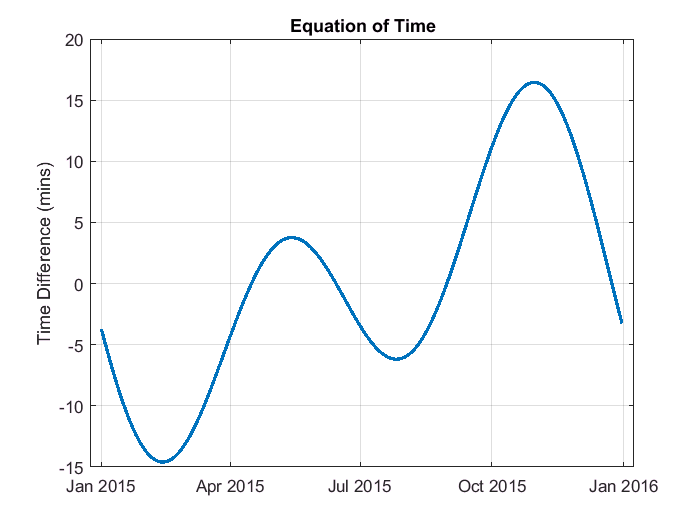

dateVal = datetime(2015,1,day); % Vector of days of year
M = 2*pi/365*(day-81);          % Mean Anomaly

% Equation of Time - Earth
equationOfTime = 9.87*sin(2*M) - 7.53*cos(M) - 1.5*sin(M);

% Plot Equation of Time
figure;
plot(dateVal,equationOfTime,'LineWidth',2);
grid on;
title('Equation of Time');
ylabel('Time Difference (mins)')

The above plot illustrates how the apparent time of solar noon changes over the course of a year. When the Time Difference is negative, apparent solar noon occurs after 12:00 pm clock time noon. Contrastingly, a positive Time Difference indicates a solar noon that occurs prior to 12:00 pm clock time.

## Calculate Position of Sun

The position of the sun depends not only on the time, but also the latitude.  The following "sunPosition" function provides the position of the sun for entire year. More information on calculating the celestial solar position can be found in the "sunPosition" function.

[azimuth,elevation] = sunPosition(day,hours(time),observationLatitude);

% Convert Spherical Coordinates to Cartesian
[x,y,z] = sph2cart(azimuth'*pi/180,elevation'*pi/180,1);

% Remove sun positions below horizon
zAbove = z; zAbove(z < 0) = NaN;

## Determine when Sun above Horizon

The sun is below the horizon plenty during the year. At extremely high/low latitudes, the sun may dissipear entirely for days. (30 Days of Night, anyone?)

hoursWithSun = hours(time);
hoursWithSun(~any(zAbove)) = NaN;

% Days when sun is up at least one hour
daysWithSun = day;
daysWithSun(~any(zAbove')) = NaN;

% Compute earliest and latest sunrise/sunset for this latitude
firstHour = find(mod(hoursWithSun,2) == 0,1,'first');
lastHour = find(mod(hoursWithSun,2) == 0,1,'last');

% Compute first and last day with sun for this latitude
firstDay = find(~isnan(daysWithSun),1,'first')

firstDay = 1

lastDay = find(~isnan(daysWithSun),1,'last')

lastDay = 365

## Plot Sun Trajectories over Year

Plotting the sun's trajectory over the course of a year should reveal some obvious facts. Summer days are longer, winter days are shorter. The spring/fall have day lengths that change rapidly over each day.

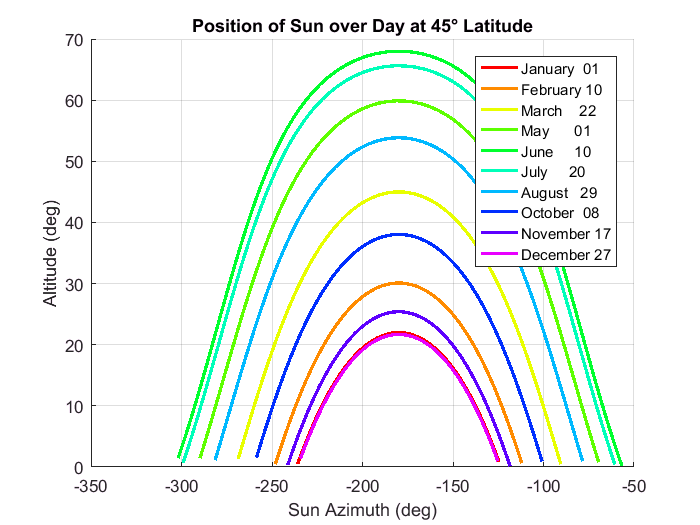

dayVec = firstDay:40:lastDay;

figure;
timeSub = 5:numel(time)-5;
set(gca, 'ColorOrder', hsv(numel(dayVec)+1)); hold on;

elevationUp = elevation;   elevationUp(elevationUp < 0) = NaN;
for i = dayVec,
    plot(azimuth(timeSub,i),elevationUp(timeSub,i),'LineWidth',2);
end
legend(datestr(dateVal(dayVec),'mmmm dd')); grid on;
title(['Position of Sun over Day at ' num2str(observationLatitude) ...
    '° Latitude']);   
ylabel('Altitude (deg)');
xlabel('Sun Azimuth (deg)');

## Plot Analemma

Using the trajectory of the sun over the course of the year, we can take a "snapshot" of the position of the sun at the same time every day. Plotting this snapshot of time reveals the analemma.

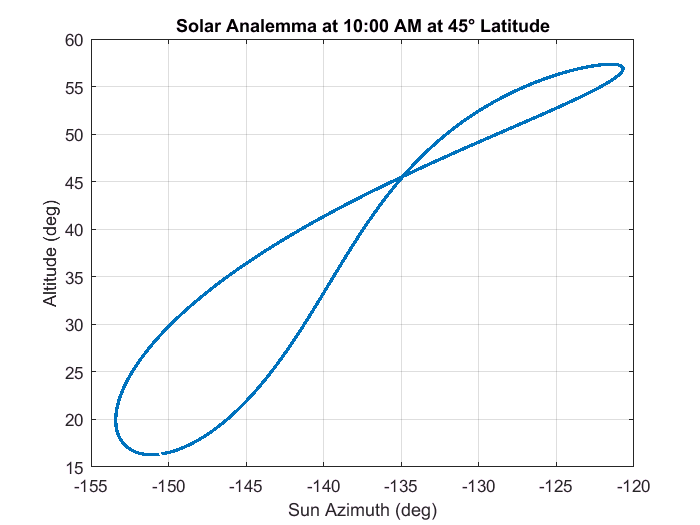

figure;
snapTime = time == hours(timeSnapshot);
plot(azimuth(snapTime,:),elevationUp(snapTime,:),'LineWidth',2); grid on;
title(['Solar Analemma at ' datestr(time(time == hours(timeSnapshot)),16)...
    ' at ' num2str(observationLatitude) '° Latitude']);   
ylabel('Altitude (deg)');
xlabel('Sun Azimuth (deg)');

## Plot Hourly Analemma

The analemma in the previous plot is for a single time. We can also take several snapshots of the sun's position and plot multiple analemmas. To a viewer on the ground, the analemma would appear on the sky's hemisphere.

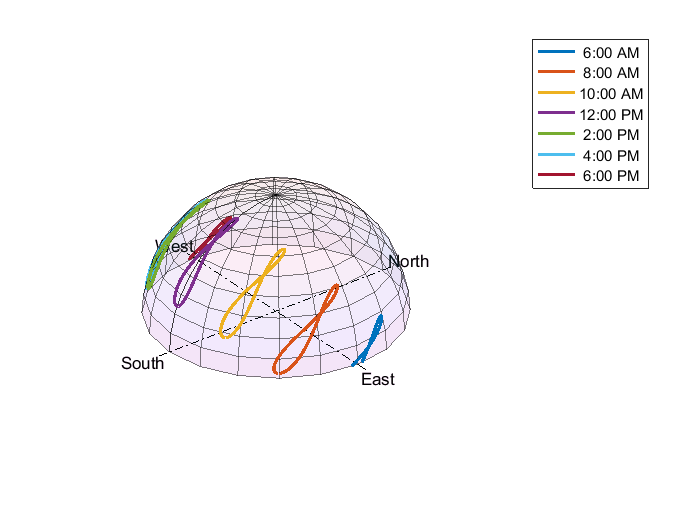

% Time Vector to plot Analemma
timeVec = firstHour:12:lastHour;

% Select subset of possible analemmas to plot
xSnap = x(:,timeVec);
ySnap = y(:,timeVec);
zSnap = zAbove(:,timeVec);

% Plot analemmas for selected latitude
figure;
singlePlot = plot3(xSnap,ySnap,zSnap,'LineWidth',2);
legend(datestr(time(timeVec),16));
hold on;
plotVisibleHemisphere();

## Analemma Animation

Just for fun, we can also animate the sun's trajectory and grab snapshots of the sun over the course of a year. You can try the same process with the actual sun and a fixed camera!

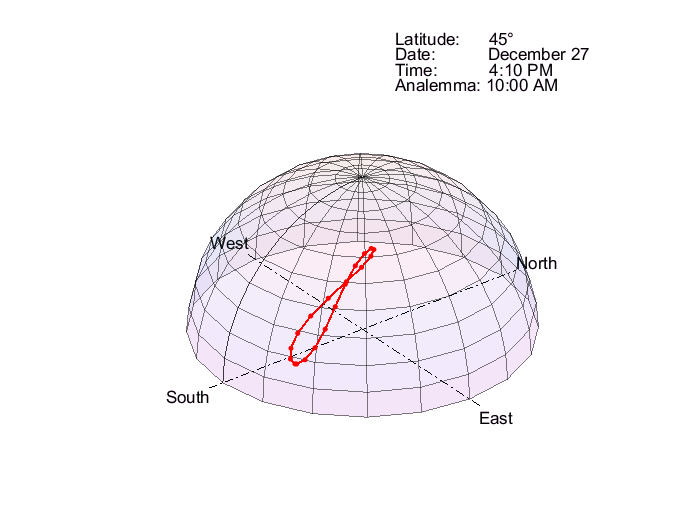

% Plot Visible Hemisphere for Solar Animation
figure;
plotVisibleHemisphere();
hold on;

% Initialize Date/Time Text Legends
dateLabel = text(1,1,1,'');
timeLabel = text(1,1,0.9,'');
analemmaLabel = text(1,1,0.8,['Analemma: ' datestr(time(time == hours(timeSnapshot)),16)]);
latitudeLabel = text(1,1,1.1,['Latitude:      ' num2str(observationLatitude) '°']);

% Initialize Sun/Analemma Objects for Plot
sun = plot3(NaN,NaN,NaN,'o','MarkerSize',12,'MarkerFaceColor','yellow');
analemmaLine = plot3(NaN,NaN,NaN,'.-','LineWidth',1.25,'MarkerSize',9);
analemmaLine.Color = 'red';

for i = 1:20:numel(day),
    
    dateLabel.String = ['Date:           ' datestr(dateVal(i),'mmmm dd')]; 
    
    for j = 1:numel(time),
        if ~isnan(zAbove(i,j)),
            
            timeLabel.String = ['Time:          ' datestr(time(j),16)];
            
            sun.XData = x(i,j);
            sun.YData = y(i,j);
            sun.ZData = zAbove(i,j);

            if time(j) == hours(timeSnapshot),
                analemmaLine.XData = [analemmaLine.XData(1:end) x(i,j)];
                analemmaLine.YData = [analemmaLine.YData(1:end) y(i,j)];
                analemmaLine.ZData = [analemmaLine.ZData(1:end) z(i,j)];
            end
            drawnow
            
        end

    end
end

% Final Sunset
sun.delete;

## References

[Wikipedia: Analemma](https://en.wikipedia.org/wiki/Analemma)

[Wikipedia: Equation of Time](https://en.wikipedia.org/wiki/Equation_of_time)

Copyright 2016 The MathWorks, Inc.